# LME Tutorial 1: Basics

## Global parameters

clear % clear workspace
close all % close figures
% seed = 'shuffle'; % random seed
seed = 0; % defined seed (here: 0)
rng(seed); % set random seed
N = 100; % number of subjects

## Influence of chocolate on weight

Initial weight variability

std_w = 5;

Measurement error

eps = 0.01;

Initial weight distribution

Weight1_true = 70 + std_w * randn(N,1);
Weight1 = Weight1_true + eps * randn(N,1);

Effect of eating chocolate

beta = 0.1; % 0.1 kg increase

Final weight

Weight2 = Weight1_true + beta + eps*randn(N,1); % final weight

Histogr am with Gaussian fit

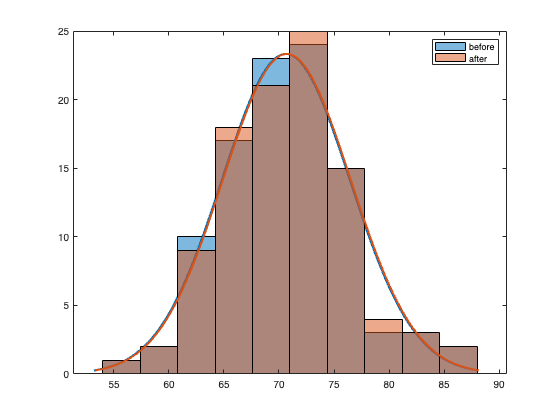

figure
cmap = colormap('lines');
h1 = histfit(Weight1);
h1(1).FaceColor = cmap(1,:);
h1(1).FaceAlpha = 0.5;
h1(2).Color = cmap(1,:);
hold on
h2 = histfit(Weight2);
h2(1).FaceColor = cmap(2,:);
h2(1).FaceAlpha = 0.5;
h2(2).Color = cmap(2,:);
legend([h1(1), h2(1)],{'before','after'})
hold off

## T-test

unpaired t-test

[~,p] = ttest2(Weight1,Weight2)

p = 0.9037

paired t-test

[~,p] = ttest(Weight1,Weight2)

p = 2.0535e-82

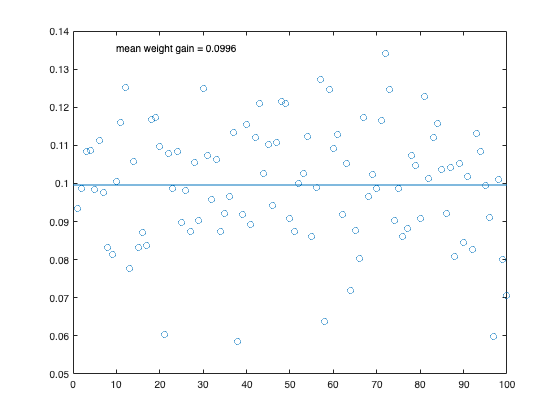

Gain = Weight2-Weight1;
plot(Gain,'o')
hold on
line([0,length(Gain)],[mean(Gain),mean(Gain)]);
text(0.1,0.95,sprintf('mean weight gain = %.4f',mean(Gain)),'Units','normalized');
hold off

## ANOVA

Subject1 = categorical((1:N)');
Time1 = repmat({'before'},N,1);
Subject2 = categorical((1:N)');
Time2 = repmat({'after'},N,1);
Subject = [Subject1;Subject2];
Time = [Time1;Time2];
Weight = [Weight1;Weight2];

1-way ANOVA

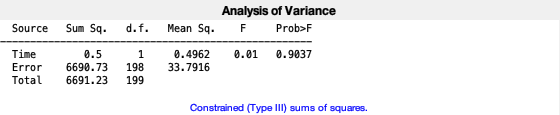

ans = 0.9037

anovan(Weight,{Time},'varnames',{'Time'})

2-way ANOVA with Subject as factor

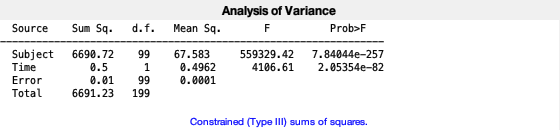

ans = 1.0e-81 *

    0.0000
    0.2054


anovan(Weight,{Subject,Time},'varnames',{'Subject','Time'})

## Linear model

First create data table in long format (with observations as rows)

Data = table;
Data.Subject = Subject;
Data.Time = Time;
Data.Weight = Weight;
% convert to categorical
Data.Subject = categorical(Data.Subject);
Data.Time = categorical(Data.Time);
% sort by subject
Data = sortrows(Data,{'Subject'});
head(Data)

ans = 8×3 table
    Subject     Time     Weight
    _______    ______    ______

       1       before    72.697
       1       after      72.79
       2       before    79.161
       2       after     79.259
       3       before    58.707
       3       after     58.815
       4       before    74.305
       4       after     74.414


% save data table to Excel file
writetable(Data,'Chocolate_LM1.xlsx');

## Null model

formula = 'Weight ~ 1'

formula = 'Weight ~ 1'

mdl0 = fitlme(Data,formula)

mdl0 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             200
    Fixed effects coefficients           1
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    Weight ~ 1

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1273.6    1280.2    -634.81          1269.6  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE       tStat     DF     pValue         Lower     Upper 
    {'(Intercept)'}        70.665      0.409    172.77    199    8.7891e-219    69.858    71.471

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        5.7841      5.2442    6.3797


stats0 = anova(mdl0)

stats0 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat    DF1    DF2    pValue     
    {'(Intercept)'}        29851    1      199    8.7891e-219


Check goodness of fit

mdl = mdl0;
RSquared = mdl.Rsquared.Ordinary

RSquared =      0


Plot residuals

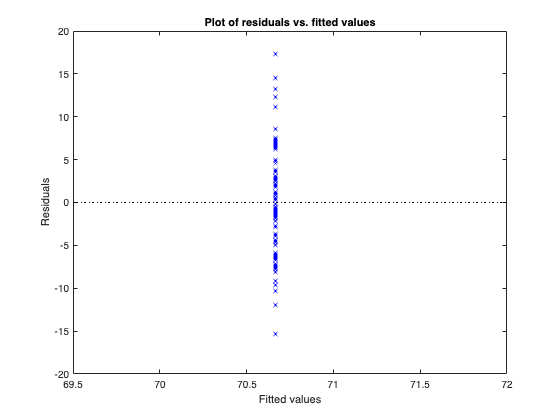

figure
plotResiduals(mdl,'fitted');

## Fixed-effects model

formula = 'Weight ~ Time'

formula = 'Weight ~ Time'

mdl1 = fitlme(Data,formula)

mdl1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             200
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    Weight ~ 1 + Time

Model fit statistics:
    AIC                 BIC                 LogLikelihood        Deviance        
    1275.60761005087    1285.50256215051    -634.803805025435    1269.60761005087

Fixed effects coefficients (95% CIs):
    Name                   Estimate               SE                   tStat                 DF     pValue                   Lower                Upper           
    {'(Intercept)'}           70.7143187544646    0.578391328152005       122.26033709807    198    1.89412317387305e-188     69.5737209463199    71.8549165626093
    {'Time_before'}        -0.0996188815424648    0.817968860631553    -0.121788109960016    19

stats1 = anova(mdl1)

stats1 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat                DF1    DF2    pValue               
    {'(Intercept)'}         14947.5900273338    1      198    1.89412317387305e-188
    {'Time'       }        0.014832343727633    1      198        0.903190344243773


Check goodness of fit

mdl = mdl1;
RSquared = mdl.Rsquared.Ordinary

RSquared =      7.415621908546388e-05


Plot residuals

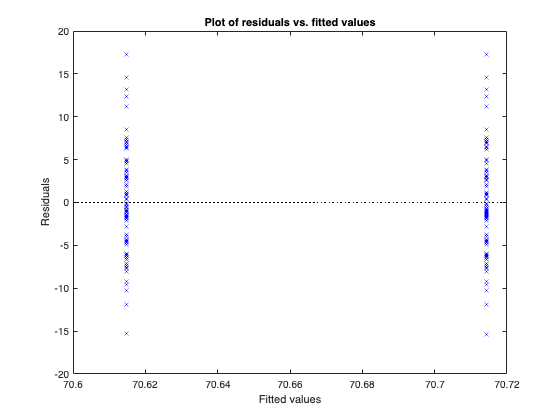

plotResiduals(mdl,'fitted');

The clustering indicates incompleteness of model!

Plot partial dependence

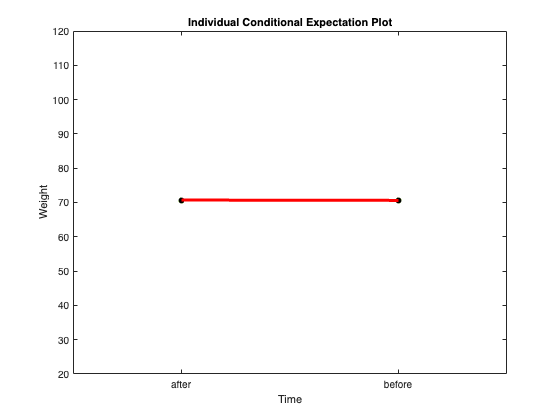

h = plotPartialDependence(mdl,'Time','Conditional','absolute');
xlim([0.5,2.5])
ylim([20,120]);

There is only a weak, global linear relation

Compare models

c01 = compare(mdl0,mdl1)

c01 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                 BIC                 LogLik               LRStat                deltaDF    pValue           
    mdl0     2     1273.62244184463    1280.21907657772    -634.811220922314                                                      
    mdl1     3     1275.60761005087    1285.50256215051    -634.803805025435    0.0148317937587308    1          0.903068618970795


The fixed-effects model is no better than the null model!

## Mixed-effects model (fixed + random effects)

formula = 'Weight ~ Time + (1|Subject)'

formula = 'Weight ~ Time + (1|Subject)'

mdl2 = fitlme(Data,formula);
stats2 = anova(mdl2)

stats2 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat               DF1    DF2    pValue               
    {'(Intercept)'}        14949.4618840271    1      198      1.871088740872e-188
    {'Time'       }        4147.57106995979    1      198    9.25330795548659e-135


Goodness of fit

mdl = mdl2;
RSquared = mdl.Rsquared.Ordinary

RSquared =    0.999998212271009


Plot residuals

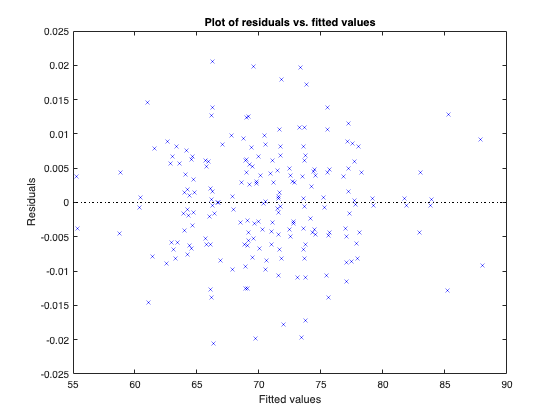

plotResiduals(mdl,'fitted');

Now the residuals are much more evenly distributed!

Plot partial dependence

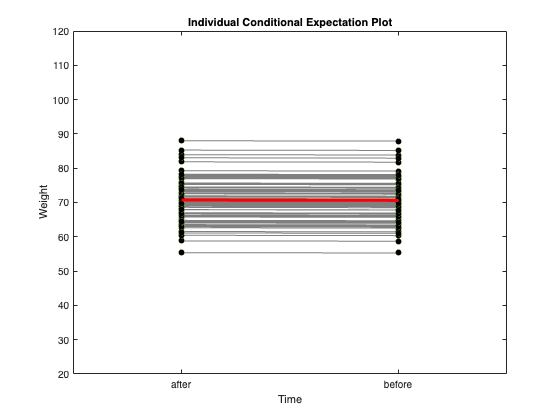

plotPartialDependence(mdl,'Time','Conditional','absolute')
xlim([0.5,2.5]);
ylim([20,120]);

Now each subject has their own fitted line!

## Compare models

c12 = compare(mdl1,mdl2)

c12 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                 BIC                 LogLik               LRStat              deltaDF    pValue
    mdl1     3     1275.60761005087    1285.50256215051    -634.803805025435                                         
    mdl2     4     92.7873019737058    105.980571439898    -42.3936509868529    1184.82030807716    1          0     


## Look at the fit results

display(mdl1)

mdl1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             200
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    Weight ~ 1 + Time

Model fit statistics:
    AIC                 BIC                 LogLikelihood        Deviance        
    1275.60761005087    1285.50256215051    -634.803805025435    1269.60761005087

Fixed effects coefficients (95% CIs):
    Name                   Estimate               SE                   tStat                 DF     pValue                   Lower                Upper           
    {'(Intercept)'}           70.7143187544646    0.578391328152005       122.26033709807    198    1.89412317387305e-188     69.5737209463199    71.8549165626093
    {'Time_before'}        -0.0996188815424648    0.817968860631553    -0.121788109960016    19

display(mdl2)

mdl2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             200
    Fixed effects coefficients           2
    Random effects coefficients        100
    Covariance parameters                2

Formula:
    Weight ~ 1 + Time + (1 | Subject)

Model fit statistics:
    AIC                 BIC                 LogLikelihood        Deviance        
    92.7873019737058    105.980571439898    -42.3936509868529    84.7873019737058

Fixed effects coefficients (95% CIs):
    Name                   Estimate               SE                     tStat                DF     pValue                   Lower                Upper             
    {'(Intercept)'}           70.7143187710457      0.578355116296166     122.267992066718    198      1.871088740872e-188     69.5737923733136      71.8548451687777
    {'Time_before'}        -0.0996188815425031    0.00154683768178564    

## Fixed or random?

formula = 'Weight ~ Time + Subject'

formula = 'Weight ~ Time + Subject'

mdl2b = fitlme(Data,formula);
stats2b = anova(mdl2b)

stats2b =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat               DF1    DF2    pValue               
    {'(Intercept)'}        175434859.178092     1     99     4.01069113177941e-311
    {'Subject'    }        1129958.42534309    99     99     5.98874819743024e-272
    {'Time'       }        8296.18105484545     1     99      2.81841038950532e-97


Goodness of fit

mdl = mdl2b;
RSquared = mdl.Rsquared.Ordinary

RSquared =    0.999998212280600


Plot residuals

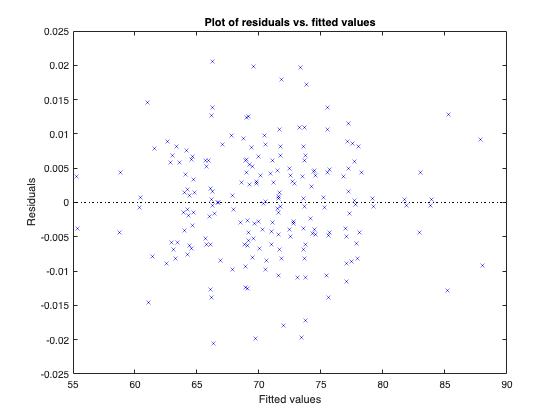

plotResiduals(mdl,'fitted');

Plot partial dependence

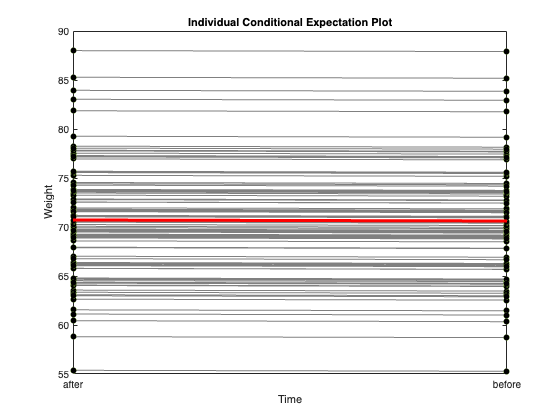

plotPartialDependence(mdl,'Time','Conditional','absolute')

Check fit

display(mdl2b)

mdl2b = Linear mixed-effects model fit by ML

Model information:
    Number of observations             200
    Fixed effects coefficients         101
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    Weight ~ 1 + Subject + Time

Model fit statistics:
    AIC                  BIC                  LogLikelihood       Deviance         
    -1173.29152389314    -836.863152505239    688.645761946569    -1377.29152389314

Fixed effects coefficients (95% CIs):
    Name                   Estimate              SE                     tStat                DF    pValue                   Lower                 Upper              
    {'(Intercept)'}          72.7932631524657    0.00549582938631464      13245.182489422    99    4.01069113177941e-311      72.7823582346343        72.804168070297
    {'Subject_2'  }          6.46638236315153    0.00773370412493516     8

## Compare models

c12b = compare(mdl1,mdl2b)

c12b =     Theoretical Likelihood Ratio Test

    Model    DF     AIC                  BIC                  LogLik               LRStat              deltaDF    pValue
    mdl1       3     1275.60761005087     1285.50256215051    -634.803805025435                                         
    mdl2b    102    -1173.29152389314    -836.863152505239     688.645761946569    2646.89913394401    99         0     


c22b = compare(mdl2,mdl2b)

c22b =     Theoretical Likelihood Ratio Test

    Model    DF     AIC                  BIC                  LogLik               LRStat              deltaDF    pValue
    mdl2       4     92.7873019737058     105.980571439898    -42.3936509868529                                         
    mdl2b    102    -1173.29152389314    -836.863152505239     688.645761946569    1462.07882586684    98         0     


## Dummy coding versus effects coding

formula = 'Weight ~ Time + (1|Subject)'
mdl2c = fitlme(Data,formula,'DummyVarCoding','effects');
stats2c = anova(mdl2c);
display(stats2)
display(mdl2.Coefficients)
display(stats2c)
display(mdl2c.Coefficients)
            
plotPartialDependence(mdl2c,'Time','Conditional','absolute')
% xlim([0.5,2.5]);
% ylim([20,120]);
line([1.5 1.5], get(gca, 'ylim'));

## Interaction effect 

N = 100;
Weight1_true = 70 + 10*randn(N,1);
Weight1 = Weight1_true + 0.1*randn(N,1);

Introduce random effect fluctuations across subjects

beta = 1 + 2*randn(N,1);

Weight at second time point

Weight2 = Weight1_true + beta + 0.1*randn(N,1);

Plot difference

scatter(0.1*randn(N,1),Weight2-Weight1,'.');
axis equal
hold on
m = mean(Weight2-Weight1);
line(get(gca,'xlim'),[m m],'Color','r','LineStyle','--');
hold off

Plot data

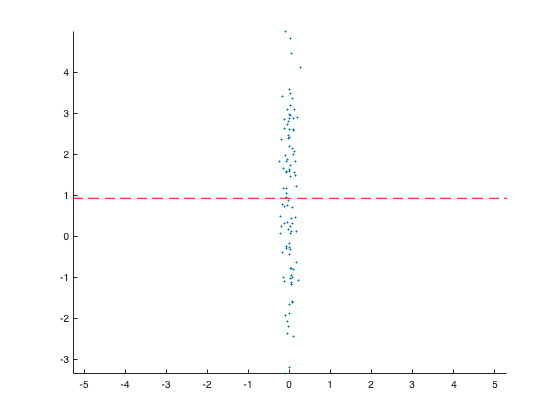

cmap = colormap('lines');

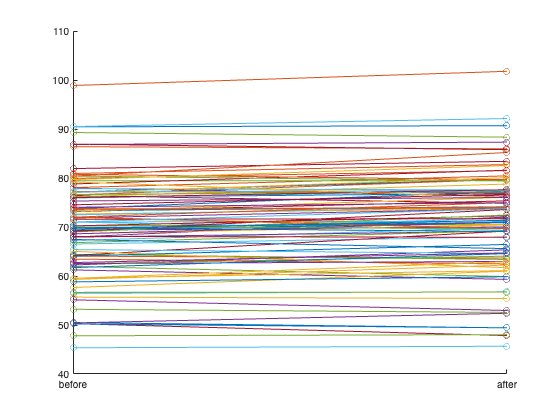

figure
hold on
for n=1:N
    c = cmap(mod(n,64)+1,:);
    plot(1,Weight1(n),'o','Color',c);
    plot(2,Weight2(n),'o','Color',c);
    line([1,2],[Weight1(n),Weight2(n)],'Color',c);
end
hold off
% xlim([0.5 2.5]);
xticks([1 2])
xticklabels({'before','after'})

Generate dataset

Subject1 = categorical((1:N)');
Time1 = repmat({'before'},N,1);
Subject2 = categorical((1:N)');
Time2 = repmat({'after'},N,1);
Subject = [Subject1;Subject2];
Time = [Time1;Time2];
Weight = [Weight1;Weight2];

Data2 = table;
Data2.Subject = Subject;
Data2.Time = Time;
Data2.Weight = Weight;
% convert to categorical
Data2.Subject = categorical(Data2.Subject);
Data2.Time = categorical(Data2.Time);
% sort by subject
Data2 = sortrows(Data2,{'Subject'});
head(Data2)

ans = 8×3 table
    Subject     Time          Weight     
    _______    ______    ________________

       1       before     64.046515464186
       1       after     63.6459560708714
       2       before    72.6453154827229
       2       after     73.8036302227649
       3       before    61.2442010831651
       3       after     59.3085898865087
       4       before     61.954918772955
       4       after     59.8861768304215


Straightforward linear mixed model

formula = 'Weight ~ Time + (1|Subject)'

formula = 'Weight ~ Time + (1|Subject)'

mdl5 = fitlme(Data2,formula,'DummyVarCoding','effects');
stats5 = anova(mdl5)

stats5 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat               DF1    DF2    pValue               
    {'(Intercept)'}        4958.69246922248    1      198    4.04181417966531e-142
    {'Time'       }        26.0647938149037    1      198      7.7251869138849e-07


mdl = mdl5;
RSquared = mdl.Rsquared.Ordinary

RSquared =    0.991662670051017


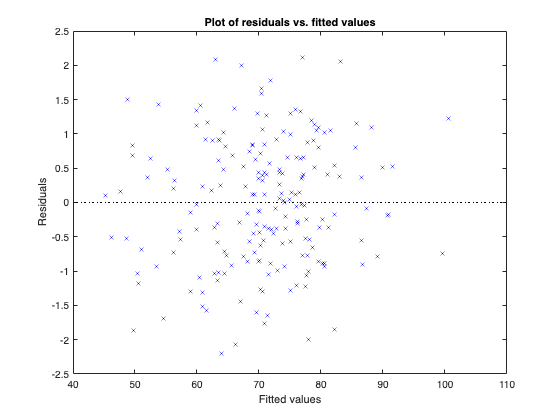

plotResiduals(mdl,'fitted');

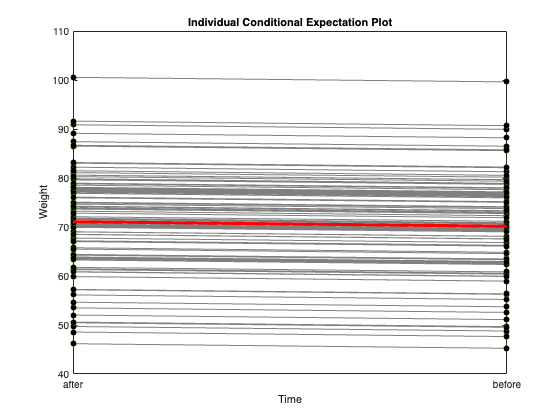

plotPartialDependence(mdl,'Time','Conditional','absolute')

Alternative, more complex linear mixed model

formula = 'Weight ~ Time + (1|Subject) + (1|Time:Subject)'

formula = 'Weight ~ Time + (1|Subject) + (1|Time:Subject)'

mdl6 = fitlme(Data2,formula,'DummyVarCoding','effects');
stats6 = anova(mdl6)

stats6 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat               DF1    DF2    pValue               
    {'(Intercept)'}        4958.68818135081    1      198    4.04214698234069e-142
    {'Time'       }        26.0648163536707    1      198     7.72510724782041e-07


mdl = mdl6;
RSquared = mdl.Rsquared.Ordinary

RSquared =    0.991678458474595


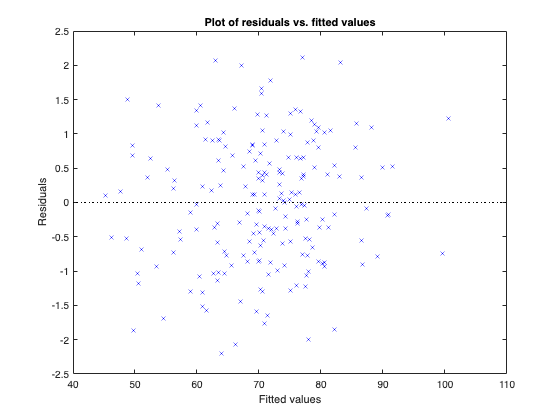

plotResiduals(mdl,'fitted');

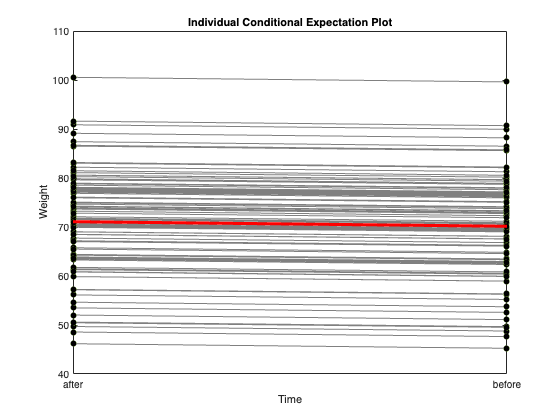

plotPartialDependence(mdl,'Time','Conditional','absolute')

2nd alternative, more complex linear mixed model

formula = 'Weight ~ Time + (Time|Subject)'

formula = 'Weight ~ Time + (Time|Subject)'

mdl7 = fitlme(Data2,formula,'DummyVarCoding','effects');
stats7 = anova(mdl7)

stats7 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat               DF1    DF2    pValue               
    {'(Intercept)'}        4958.68489889189    1      198    4.04240176872338e-142
    {'Time'       }        26.0648336032345    1      198     7.72504627766217e-07


mdl = mdl7;
RSquared = mdl.Rsquared.Ordinary

RSquared =    0.991986376341463


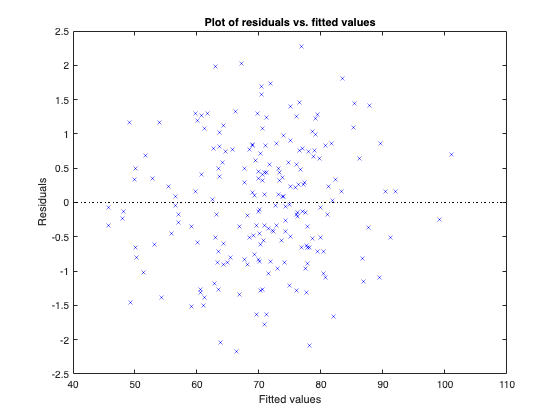

plotResiduals(mdl,'fitted');

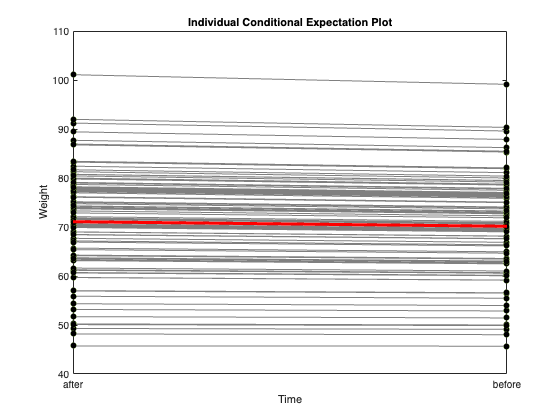

plotPartialDependence(mdl,'Time','Conditional','absolute')

## Compare models

c56 = compare(mdl5,mdl6)
c57 = compare(mdl5,mdl7)
c67 = compare(mdl6,mdl7)